clear
addpath('Experiment/Data')
load('exp3.mat')
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010

N_samples = 40e3;
t_end = N_samples/fs

t_end = 10


N_trash = 1000;
u = u(N_trash:end)

u =    -0.0322
   -1.9235
   -1.6267
    0.0606
   -0.0804
   -1.5121
   -1.5789
   -1.6647
   -0.3032
    0.2659


d = d(N_trash:end)

d =     0.8938
   -0.9828
   -0.6810
    0.8557
    0.5037
   -0.9812
   -0.9922
   -0.9536
    0.5442
    1.4011


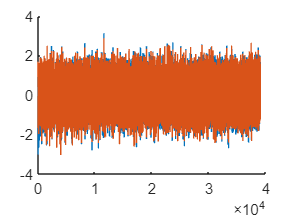


min_freq = 0.1*2*pi; %[rad/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points
%nfft = 1/min_freq*window; 
n_overlap = nfft/2;

figure()
hold on     
plot(u)
plot(d)
hold off

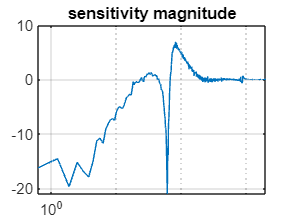


%Tf estimate
[Sud, F] = tfestimate(d,u,hann(nfft),round(nfft/2),nfft,fs); %cross spectral power density
Sdd = pwelch(d,hann(nfft)); %spectral power disturbance
Suu = pwelch(u,hann(nfft)); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Sud;
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on

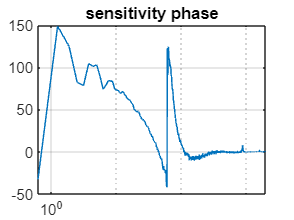


semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on

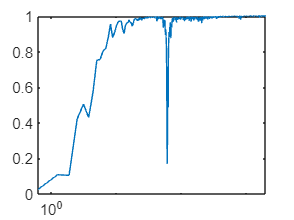


%plotting coherence 
[coherence_ry, f] = mscohere(d,u,hann(nfft),[],nfft,fs);
semilogx(f,coherence_ry)

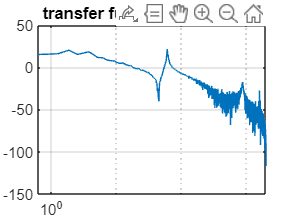

    
%plotting transfer function
L = 1./S - 1;
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on

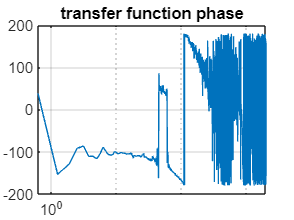


semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on